# Linear regression, GLMs and model comparison

## 2.3 Comparison of place fields across experimental conditions

We will now focus on comparing place fields across different experimental conditions using receptive fields mapped by the classical method or  by Generalized Linear Models (GLMs). We will first look into the stability and directionality of place fields across the different conditions but feel free to investigate yourself how tuning curves compare change across conditions.

### 2.3.1. Loading and preprocessing the behavioral and spiking data

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = DefineLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

### 2.3.2. Compute place fields for the pre-run, run and post-run conditions.

%Load default parameters to estimate place fields
mapsparams = DefineMapsParams(Nav,Spk);

%Computing place fields across all conditions first
Maps = MapsAnalyses(Nav, Spk.spikeTrain, mapsparams);

%List of conditions over which place fields will be estimated
condList = [1 3 5];

%Estimate place fields for each specific condition
for icond = 1:numel(condList)
    mapsparams.condition = condList(icond);
    Maps_cond(icond) = MapsAnalyses(Nav, Spk.spikeTrain, mapsparams);
end

### 2.3.3. Compute the Pearson's correlations

Compute the Pearson's correlation between place fields mapped during the pre-run and run conditions for cell #18, for left to right direction.

%selected cell ID
icell = 18;

%Maps to compare
map1 = Maps_cond(1).mapXY(icell,:,1);
map3 = Maps_cond(2).mapXY(icell,:,1);
map5 = Maps_cond(3).mapXY(icell,:,1);

%Computing the pearson's correlation
c1_3 = nansum(map1 .* map3)./sqrt(nansum(map1.^2).*nansum(map3.^2));
c3_5 = nansum(map3 .* map5)./sqrt(nansum(map3.^2).*nansum(map5.^2));

Use the **CalculatePearson.m **function to compute the correlation between place fields of all cells across all conditions.

%Correlations between pre-run and run place fields.
Corr1_3 = squeeze(CalculatePearson(Maps_cond(1).mapXY, Maps_cond(2).mapXY, 2));

%Correlations between run and post-run place fields.
Corr3_5 = squeeze(CalculatePearson(Maps_cond(2).mapXY, Maps_cond(3).mapXY, 2));

%Correlations between pre-run and post-run place fields.
Corr1_5 = squeeze(CalculatePearson(Maps_cond(1).mapXY, Maps_cond(3).mapXY, 2));

Make a scatter plot to compare the correlation values across conditions

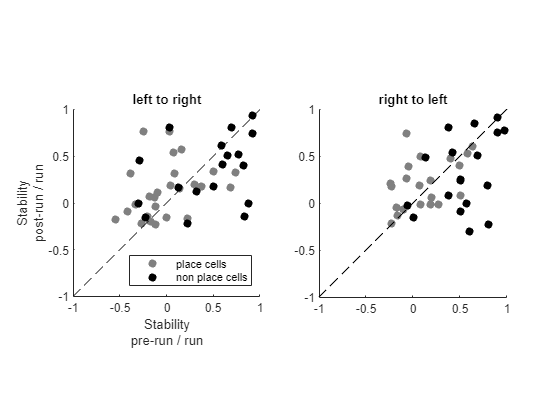

figure;

dirnames = {'right to left', 'left to right'};
placecellidx = Maps.LLH_pval <= 0.05;

for idir = 1:2
    subplot(1,2,idir)
    p1 = scatter(Corr1_3(~placecellidx,idir), Corr3_5(~placecellidx,idir),'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);
    hold on;
    p2 = scatter(Corr1_3(placecellidx,idir), Corr3_5(placecellidx,idir),'filled', 'MarkerFaceColor', [0 0 0]);
    hold on;plot([-1 1],[-1 1],'k--')
    set(gca, 'PlotBoxAspectRatio', [1 1 1])
    title(dirnames{idir})
    if idir == 1
        xlabel({'Stability', 'pre-run / run'});
        ylabel({'Stability', 'post-run / run'});
        legend([p1 p2], {'place cells','non place cells'}, 'location', 'southeast');
    end
end

Now compare correlation values between direction of travel.

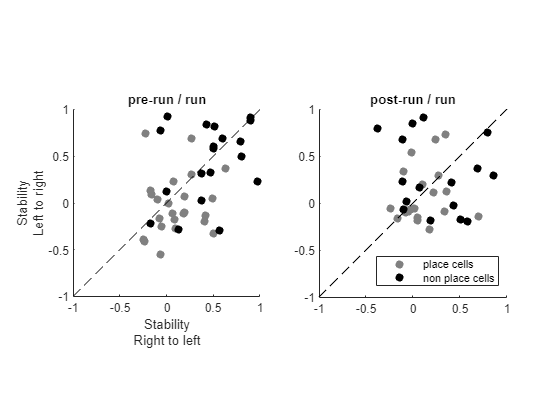

figure;

placecellidx = Maps.LLH_pval <= 0.05;


subplot(1,2,1)
scatter(Corr1_3(~placecellidx,1), Corr1_3(~placecellidx,2),'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);
hold on;
scatter(Corr1_3(placecellidx,1), Corr1_3(placecellidx,2),'filled', 'MarkerFaceColor', [0 0 0]);
hold on;plot([-1 1],[-1 1],'k--')
set(gca, 'PlotBoxAspectRatio', [1 1 1])
title('pre-run / run')

xlabel({'Stability', 'Right to left'});
ylabel({'Stability', 'Left to right'});

subplot(1,2,2)
p1 = scatter(Corr1_5(~placecellidx,1), Corr1_5(~placecellidx,2),'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);
hold on;
p2 = scatter(Corr1_5(placecellidx,1), Corr1_5(placecellidx,2),'filled', 'MarkerFaceColor', [0 0 0]);
hold on;plot([-1 1],[-1 1],'k--')
set(gca, 'PlotBoxAspectRatio', [1 1 1])
legend([p1 p2], {'place cells','non place cells'}, 'location', 'southeast');
title('post-run / run')

### 2.3.4. Selectivity compared across conditions

Compare the position selectivity of place fields across the pre-run, run and post-run conditions

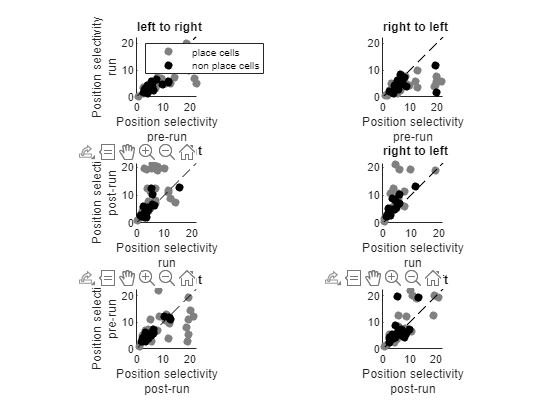

figure;

dirnames = { 'right to left', 'left to right'};
condnames = {'pre-run', 'run', 'post-run'};
placecellidx = Maps.LLH_pval <= 0.05;
condList = [1 2 3 1];

for icond = 1:3
    for idir = 1:2
        subplot(3,2,(icond-1)*2 + idir)
        k1 = condList(icond);
        k2 = condList(icond+1);
        p1 = scatter(Maps_cond(k1).SelectivityIndex(~placecellidx,idir), Maps_cond(k2).SelectivityIndex(~placecellidx,idir),'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);
        hold on;
        p2 = scatter(Maps_cond(k1).SelectivityIndex(placecellidx,idir), Maps_cond(k2).SelectivityIndex(placecellidx,idir),'filled', 'MarkerFaceColor', [0 0 0]);

        mi = min(min(Maps_cond(k1).SelectivityIndex, Maps_cond(k2).SelectivityIndex), [], 'all');
        ma = max(min(Maps_cond(k1).SelectivityIndex, Maps_cond(k2).SelectivityIndex), [], 'all');
        hold on;plot([mi ma],[mi ma],'k--');
        xlabel({'Position selectivity', condnames{k1}});

        title(dirnames{idir})
        set(gca, 'PlotBoxAspectRatio', [1 1 1],'TitleHorizontalAlignment','left')

        if idir == 1
            ylabel({'Position selectivity', condnames{k2}});
            if icond == 1
                legend([p1 p2], {'place cells','non place cells'}, 'location', 'northwest');
            end
        end
    end
end

Compare the directionality of place fields across the pre-run, run and post-run conditions

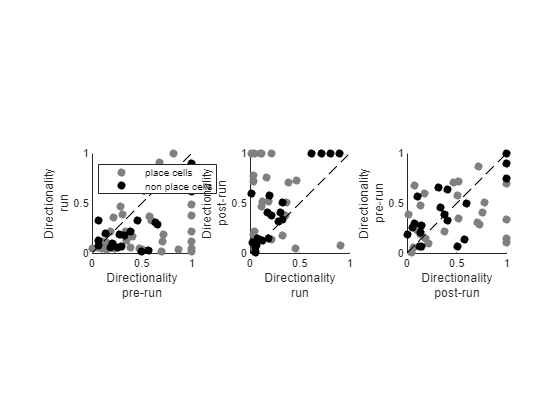

figure;

condnames = {'pre-run', 'run', 'post-run'};
placecellidx = Maps.LLH_pval <= 0.05;
condList = [1 2 3 1];

for icond = 1:3
    subplot(1,3,icond)
    k1 = condList(icond);
    k2 = condList(icond+1);
    p1 = scatter(Maps_cond(k1).DirectionalityIndex(~placecellidx), Maps_cond(k2).DirectionalityIndex(~placecellidx),'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);
    hold on;
    p2 = scatter(Maps_cond(k1).DirectionalityIndex(placecellidx), Maps_cond(k2).DirectionalityIndex(placecellidx),'filled', 'MarkerFaceColor', [0 0 0]);

    mi = min(min(Maps_cond(k1).DirectionalityIndex, Maps_cond(k2).DirectionalityIndex), [], 'all');
    ma = max(min(Maps_cond(k1).DirectionalityIndex, Maps_cond(k2).DirectionalityIndex), [], 'all');
    hold on;plot([mi ma],[mi ma],'k--');
    xlabel({'Directionality', condnames{k1}});

    set(gca, 'PlotBoxAspectRatio', [1 1 1],'TitleHorizontalAlignment','left')

    ylabel({'Directionality', condnames{k2}});
    if icond == 1
        legend([p1 p2], {'place cells','non place cells'}, 'location', 'northwest');
    end
end